# Parameter-Dependent Spectral Submanifold Reduction for a Furuta Pendulum with Delayed Control

In this notebook, we study a Furuta pendulum stabilized by a proportional–derivative (PD) controller, considering **only the time delay in the feedback loop** and **neglecting spatial discretization**.

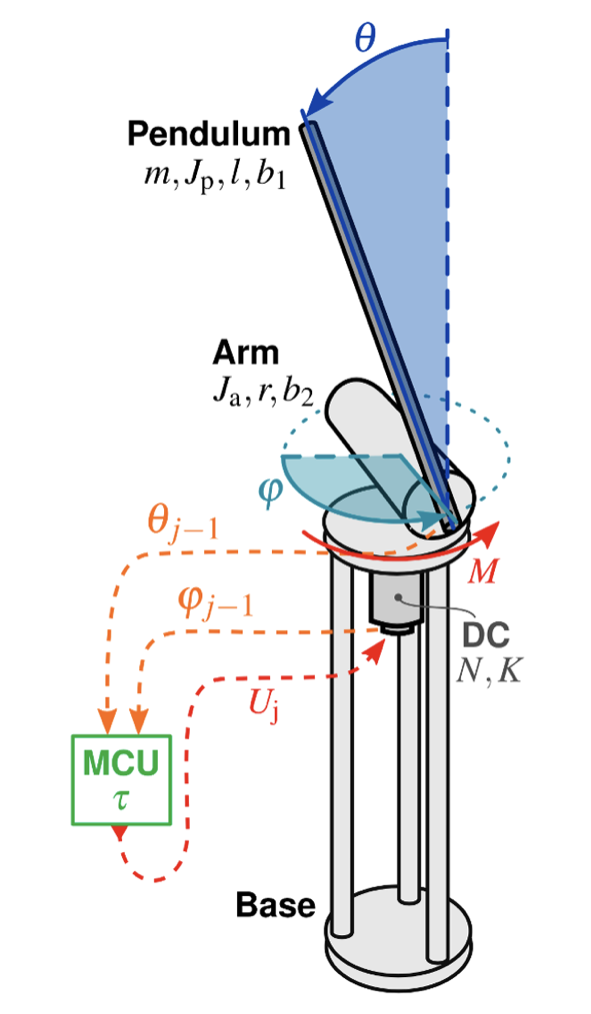      

clearvars; close all; clc;

utilsDir = fullfile(pwd,'utils');
if ~exist(utilsDir,'dir')
    error('Cannot find utils folder at %s.', utilsDir);
end
addpath(genpath(utilsDir));

variousDir = fullfile(pwd,'..','..','..','Various');
if ~exist(variousDir,'dir')
    error('Cannot find Various folder at %s.', variousDir);
end
addpath(genpath(variousDir));

run(fullfile(variousDir,'install.m'));  

SSMLearn: Data-driven Reduced Order Models for Nonlinear Dynamical Systems
License: GNUv3.0


SSMLearn successfully installed!
 
Checking SSMTool is installed...


We compute a **parameter-dependent SSM reduced-order model** by first constructing **autonomous spectral submanifolds (SSMs)** at few parameter values (here, the **feedback delay**). The corresponding **manifold parametrizations and reduced dynamics** are then interpolated across the parameter space. Using the interpolated models, we visualize **phase portraits at parameter values not included in the training set**. For a chosen **query parameter**, we interpolate the invariant manifold and its reduced dynamics, generate **full system trajectories**, and compare them with the **parametric SSM-reduced model predictions **to assess the model's generalization capabilities.

- Zhang, Y. (2025). *Phase Portrait Plotter on 2D Phase Plane*. MATLAB Central File Exchange.Available at: [https://www.mathworks.com/matlabcentral/fileexchange/110785-phase-portrait-plotter-on-2d-phase-plane](https://www.mathworks.com/matlabcentral/fileexchange/110785-phase-portrait-plotter-on-2d-phase-plane)(Adapted for phase portrait generation.)

- Henning, J. (2025). *Interpolation Utilities*. MATLAB Central File Exchange.Available at: https://ch.mathworks.com/matlabcentral/fileexchange/36800-interpolation-utilitiesRetrieved.

figOpts = { ...
    'Interpreter',     'latex', ...
    'FontName',        'Helvetica', ...
    'FontSizeAxes',    30, ...
    'FontSizeLabels',  30, ...
    'FontSizeTitle',   30, ...
    'BackgroundColor', 'white', ...
    'Grid',            'on', ...
    'AxesLineWidth',   2, ...
    'PlotLineWidth',   1, ...
    'Box',             'on', ...
    'ScreenCoverage',  0.9 ...
};

% Parameters
config.SSMDim              = 4;
config.SSMOrder            = 1;
config.RedDynOrder         = 6;
config.numVars             = config.SSMDim;
config.Kp                  = 15.5;     % proportional gain [V]
config.Kd                  = 5.45;     % derivative gain [Vs]
config.mu_values           = [30.5, 31, 32, 32.5]; 
config.folderPattern       = 'Ts%gms_FurutaTimeDelay';
config.useSavedPolynomials = false;    % set true to reuse polynomials.mat
config.interpMethodDynamicsPP        = 'linear'; % 'linear' | 'spline'  % phase space plot
config.interpMethodManifold        = 'linear'; % 'constant' | 'linear' | 'spline' | 'bulirschstoer' | 'floaterhormann' | 'ratint' | 'barylag' %traj predictions
config.interpMethodDynamics        = 'linear'; % 'constant' | 'linear' | 'spline' | 'bulirschstoer' | 'floaterhormann' | 'ratint' | 'barylag' %traj predictions

config.TsResolution        = 100;  

fprintf('Interpolation method for the manifold: %s\n', config.interpMethodManifold);

Interpolation method for the manifold: linear


fprintf('Interpolation method for the reduced dynamics: %s\n', config.interpMethodDynamics);

Interpolation method for the reduced dynamics: linear



% Compute polynomials
polynomialsFile = fullfile(utilsDir, 'polynomials.mat');
if config.useSavedPolynomials && isfile(polynomialsFile)
    load(polynomialsFile, 'polynomials', '-mat');
else
    polynomials = loadReducedPolynomials(config);
    save(polynomialsFile, 'polynomials');
end

Loading from: IMInfoRDInfoForTraining/Ts30.5ms_FurutaTimeDelay/RDInfo.matLoading from: IMInfoRDInfoForTraining/Ts31ms_FurutaTimeDelay/RDInfo.matLoading from: IMInfoRDInfoForTraining/Ts32ms_FurutaTimeDelay/RDInfo.matLoading from: IMInfoRDInfoForTraining/Ts32.5ms_FurutaTimeDelay/RDInfo.mat

interpStruct = structureForInterpolation(polynomials);
save(polynomialsFile, 'polynomials', 'interpStruct');

## **Phase-Space Structure at Unseen Delay Values**

Here, we perform a **parameter sweep over the sampling delay** by evaluating the **interpolated SSM-reduced dynamics**at delay values not used in training. Using the interpolated manifold and reduced dynamics, **phase portraits in the reduced (ρ1,ρ2)(ρ1�,ρ2�)-coordinates** are generated over a dense set of query delays. This reveals the **emergence of an unstable 3-torus** in phase space through a **global heteroclinic bifurcation**, followed by its **disappearance via a subcritical Hopf bifurcation of the stable 2-torus**.

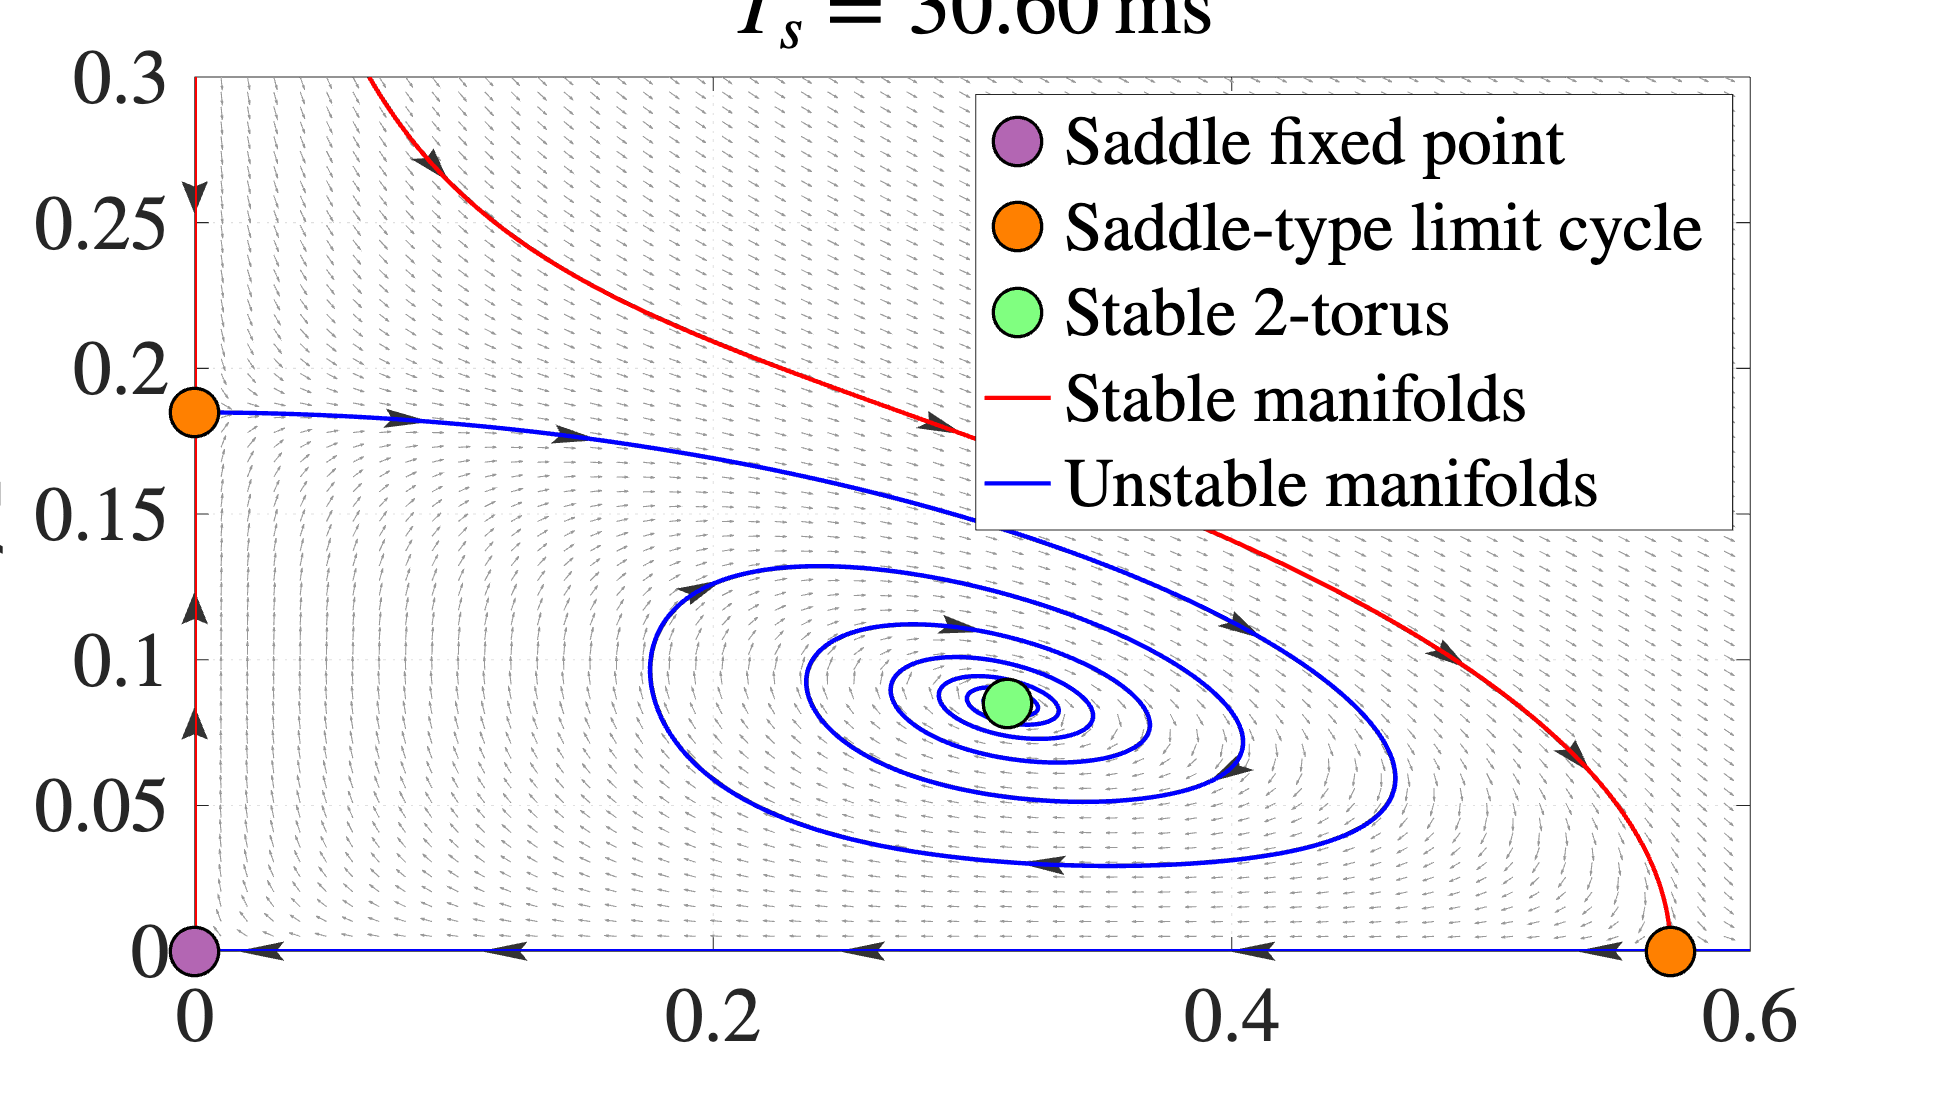

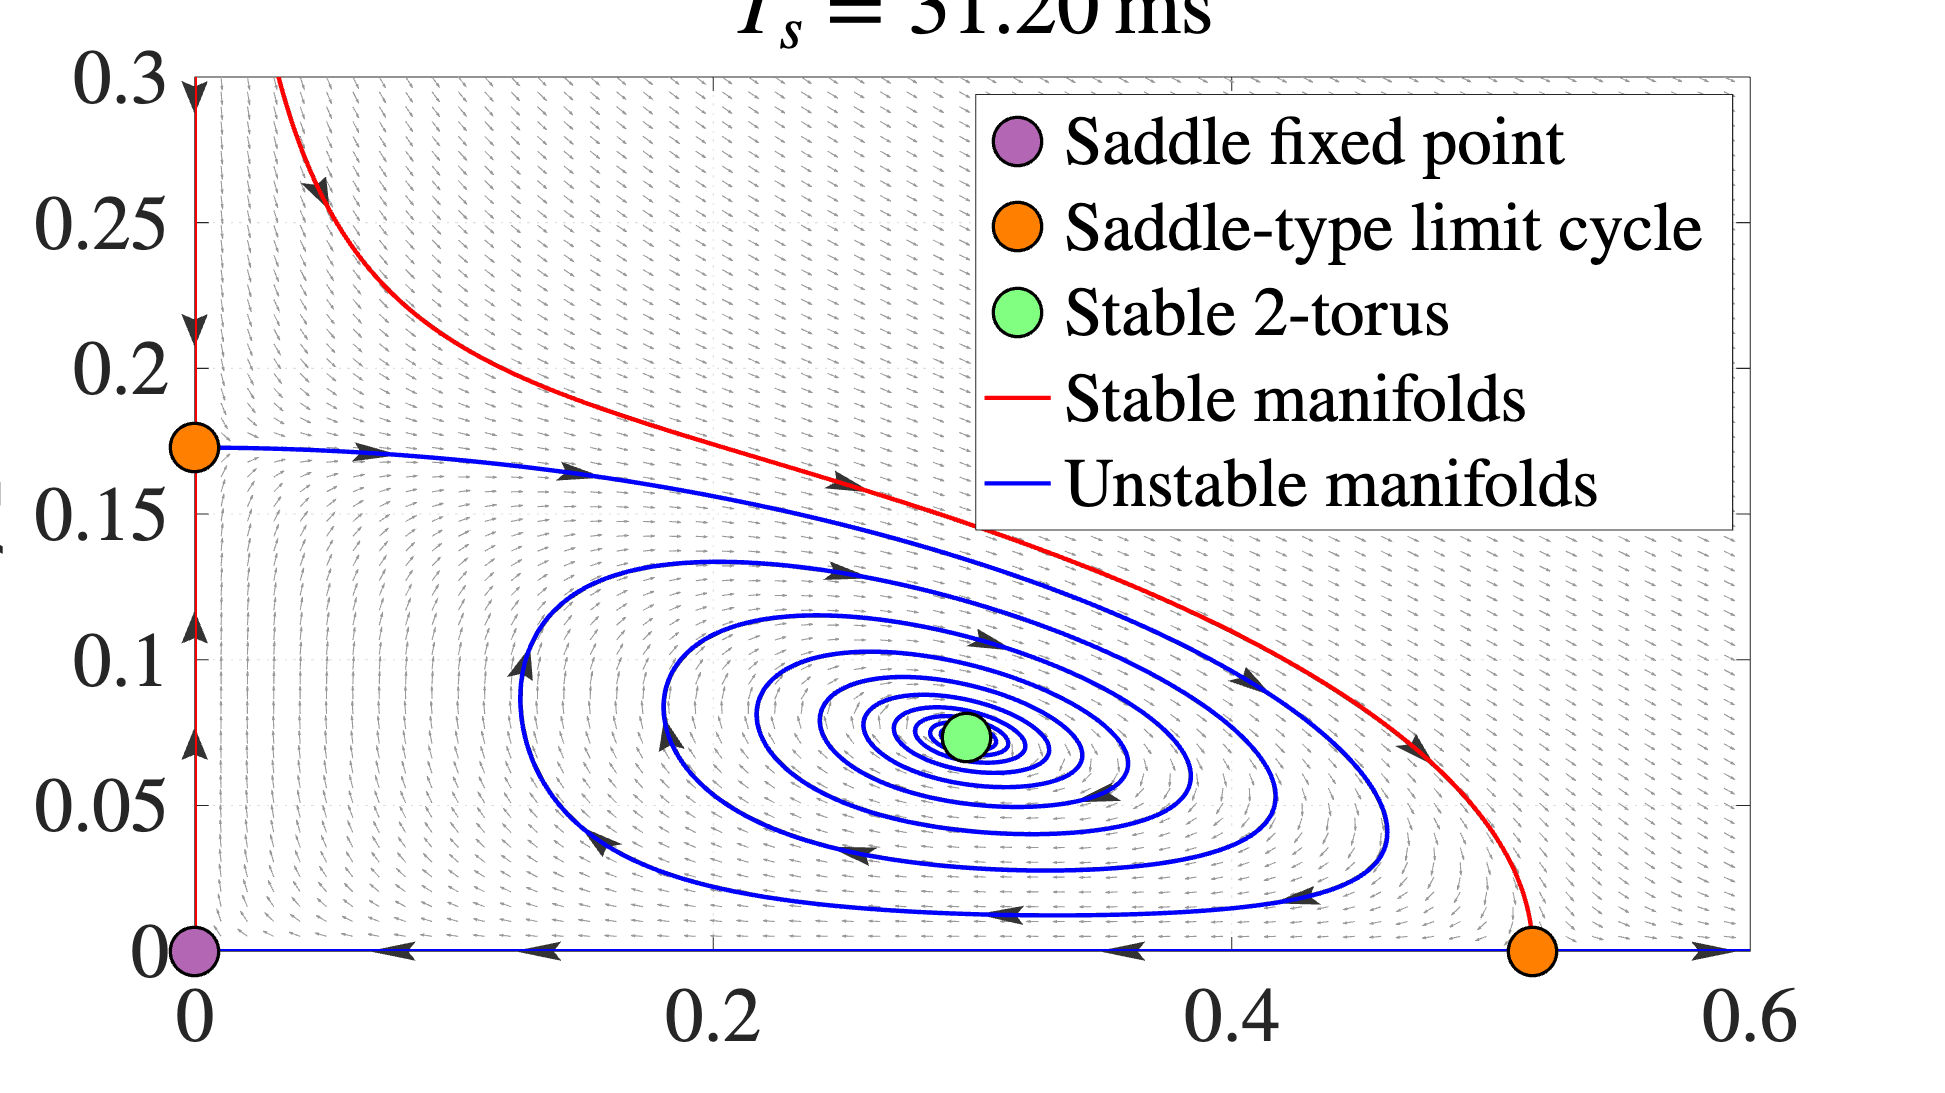

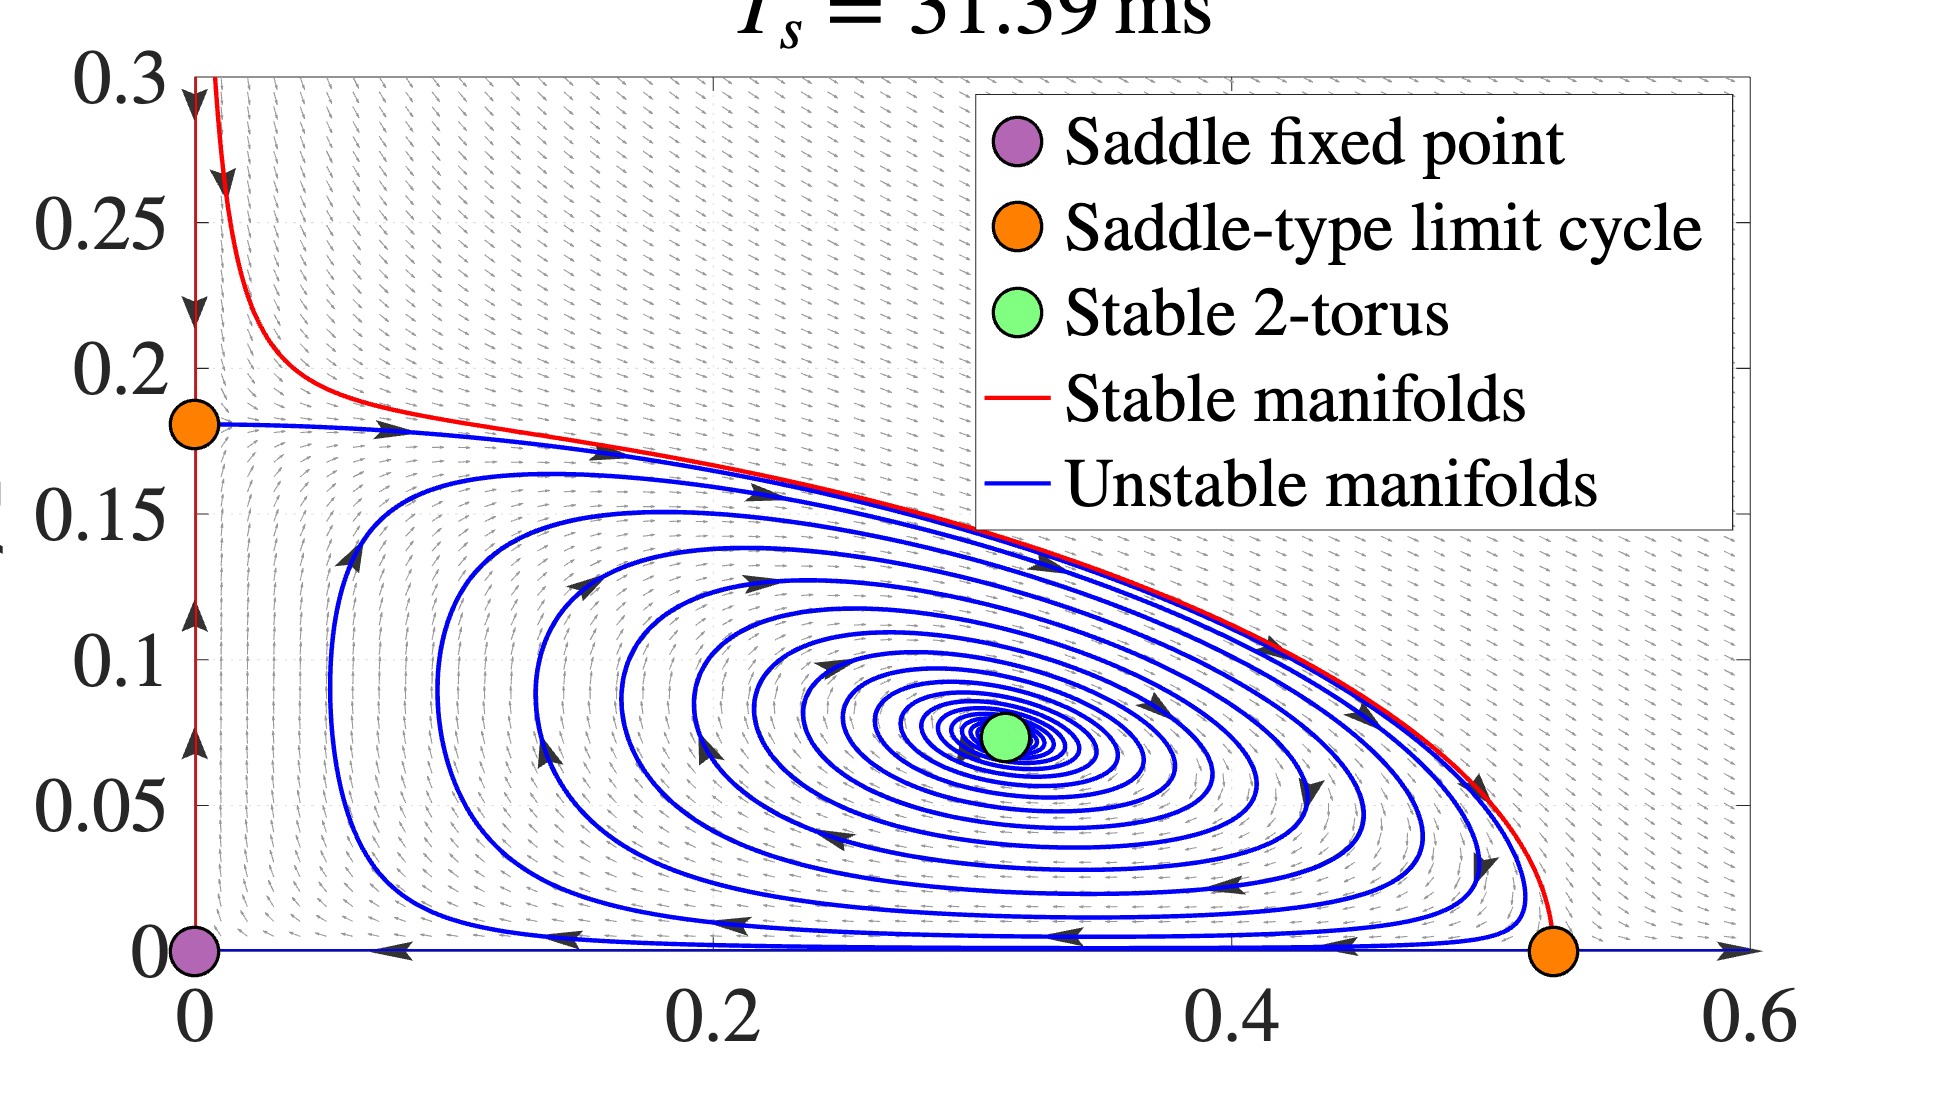

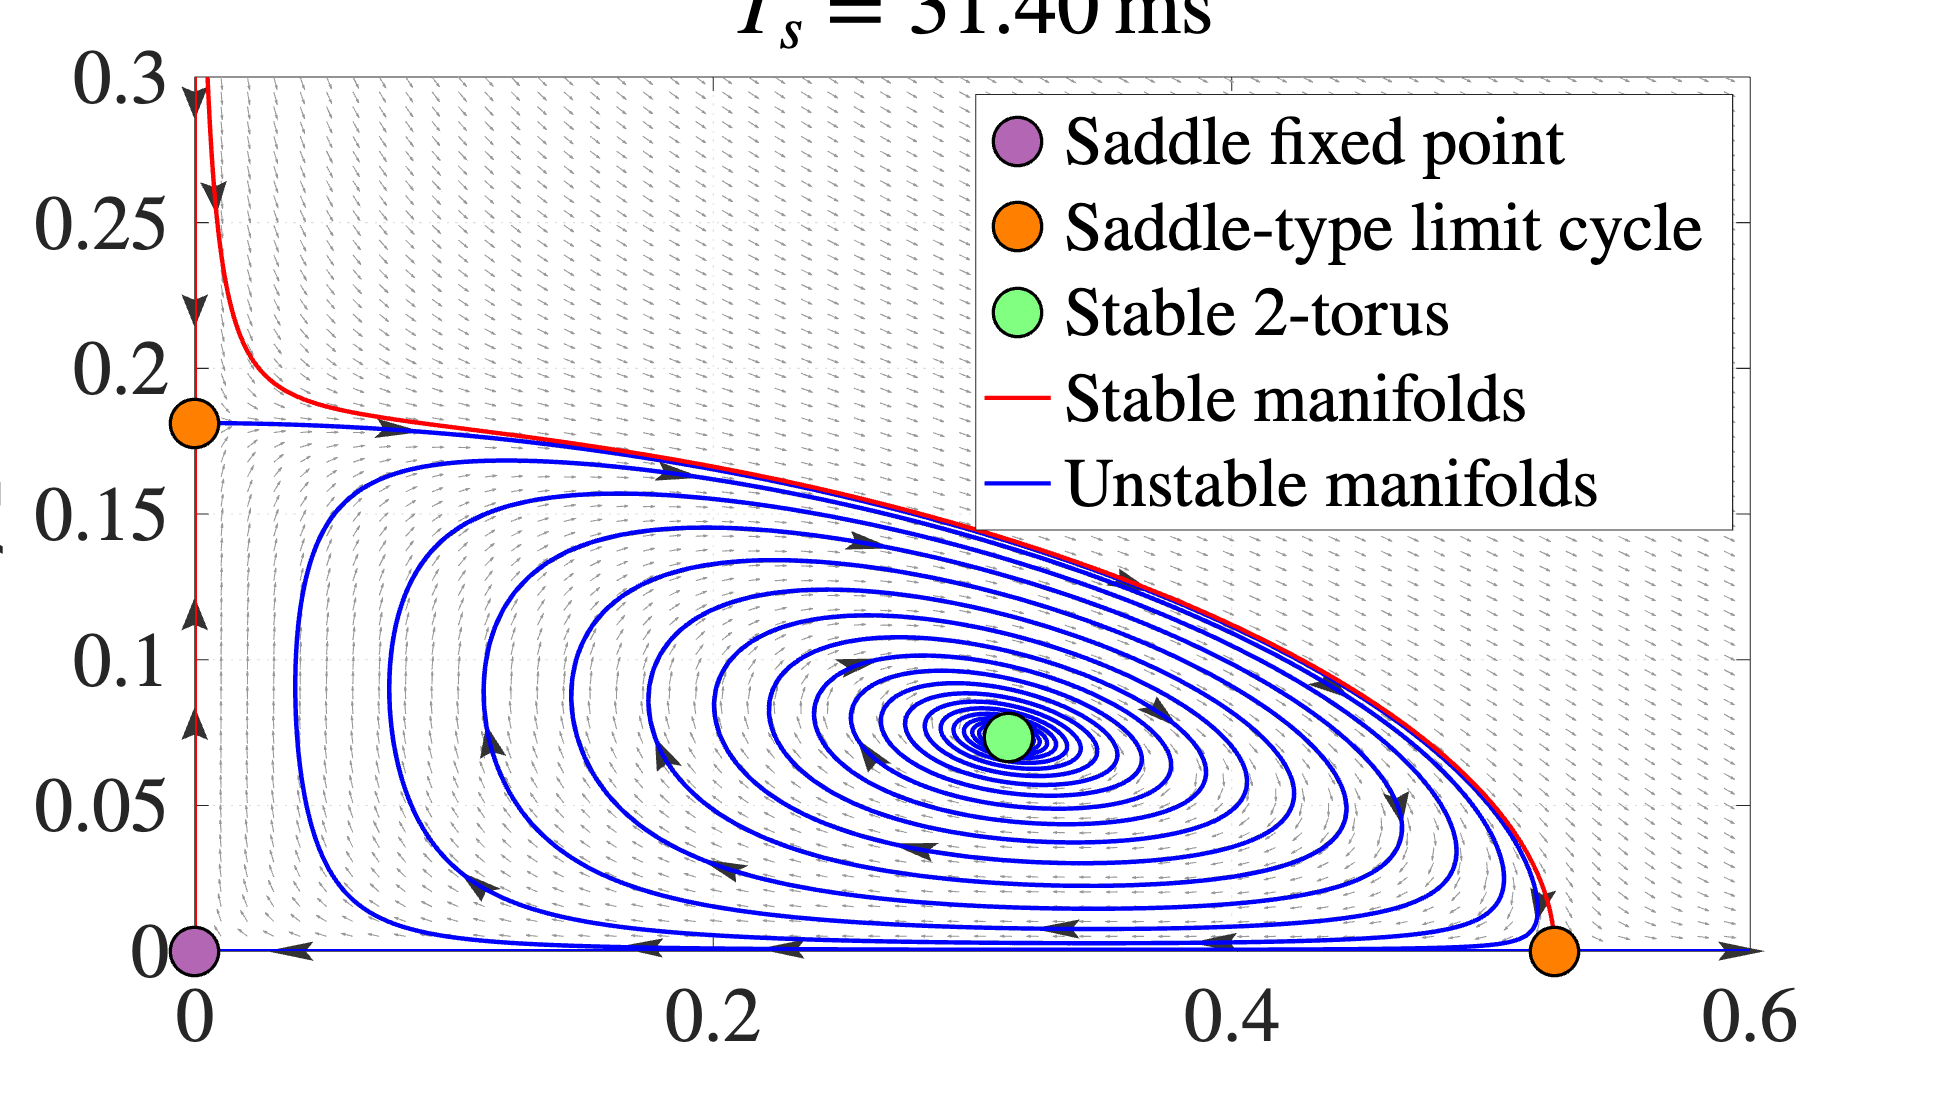

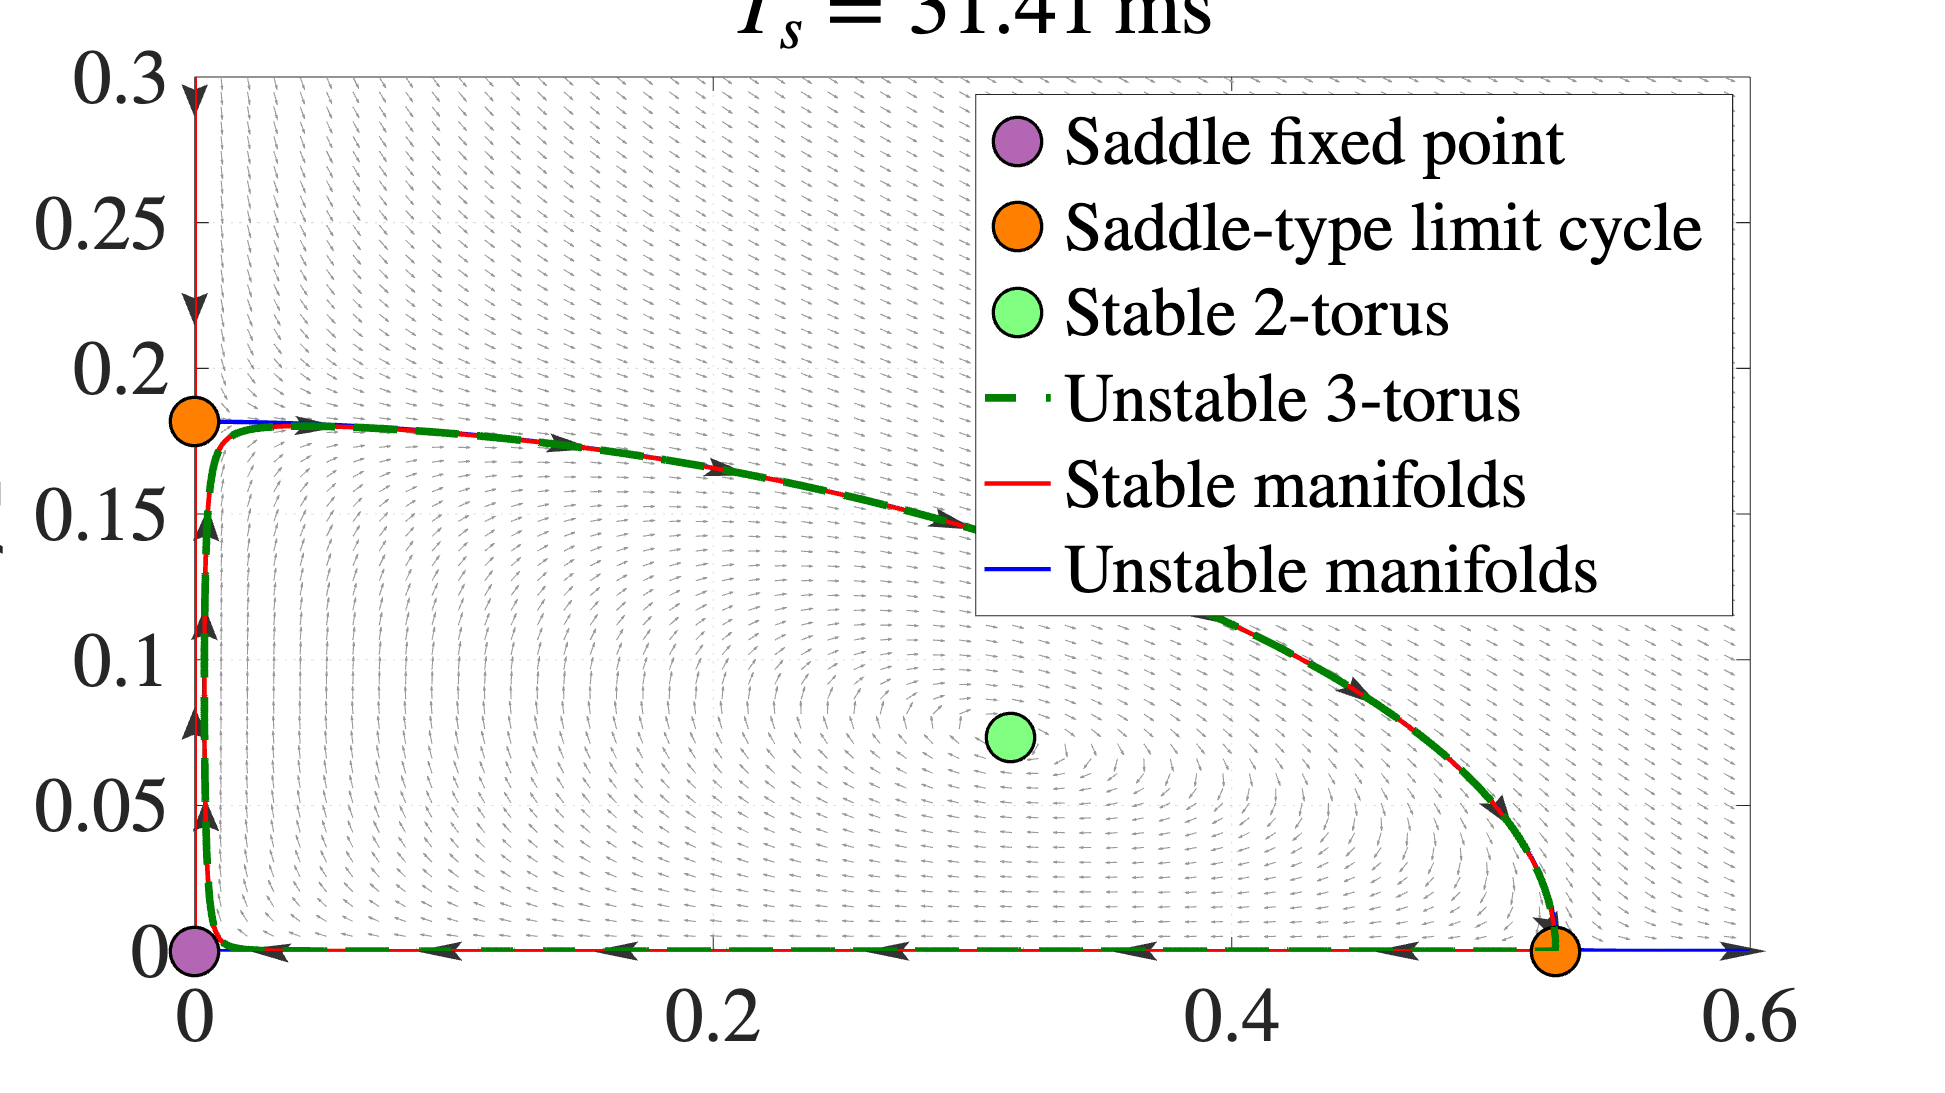

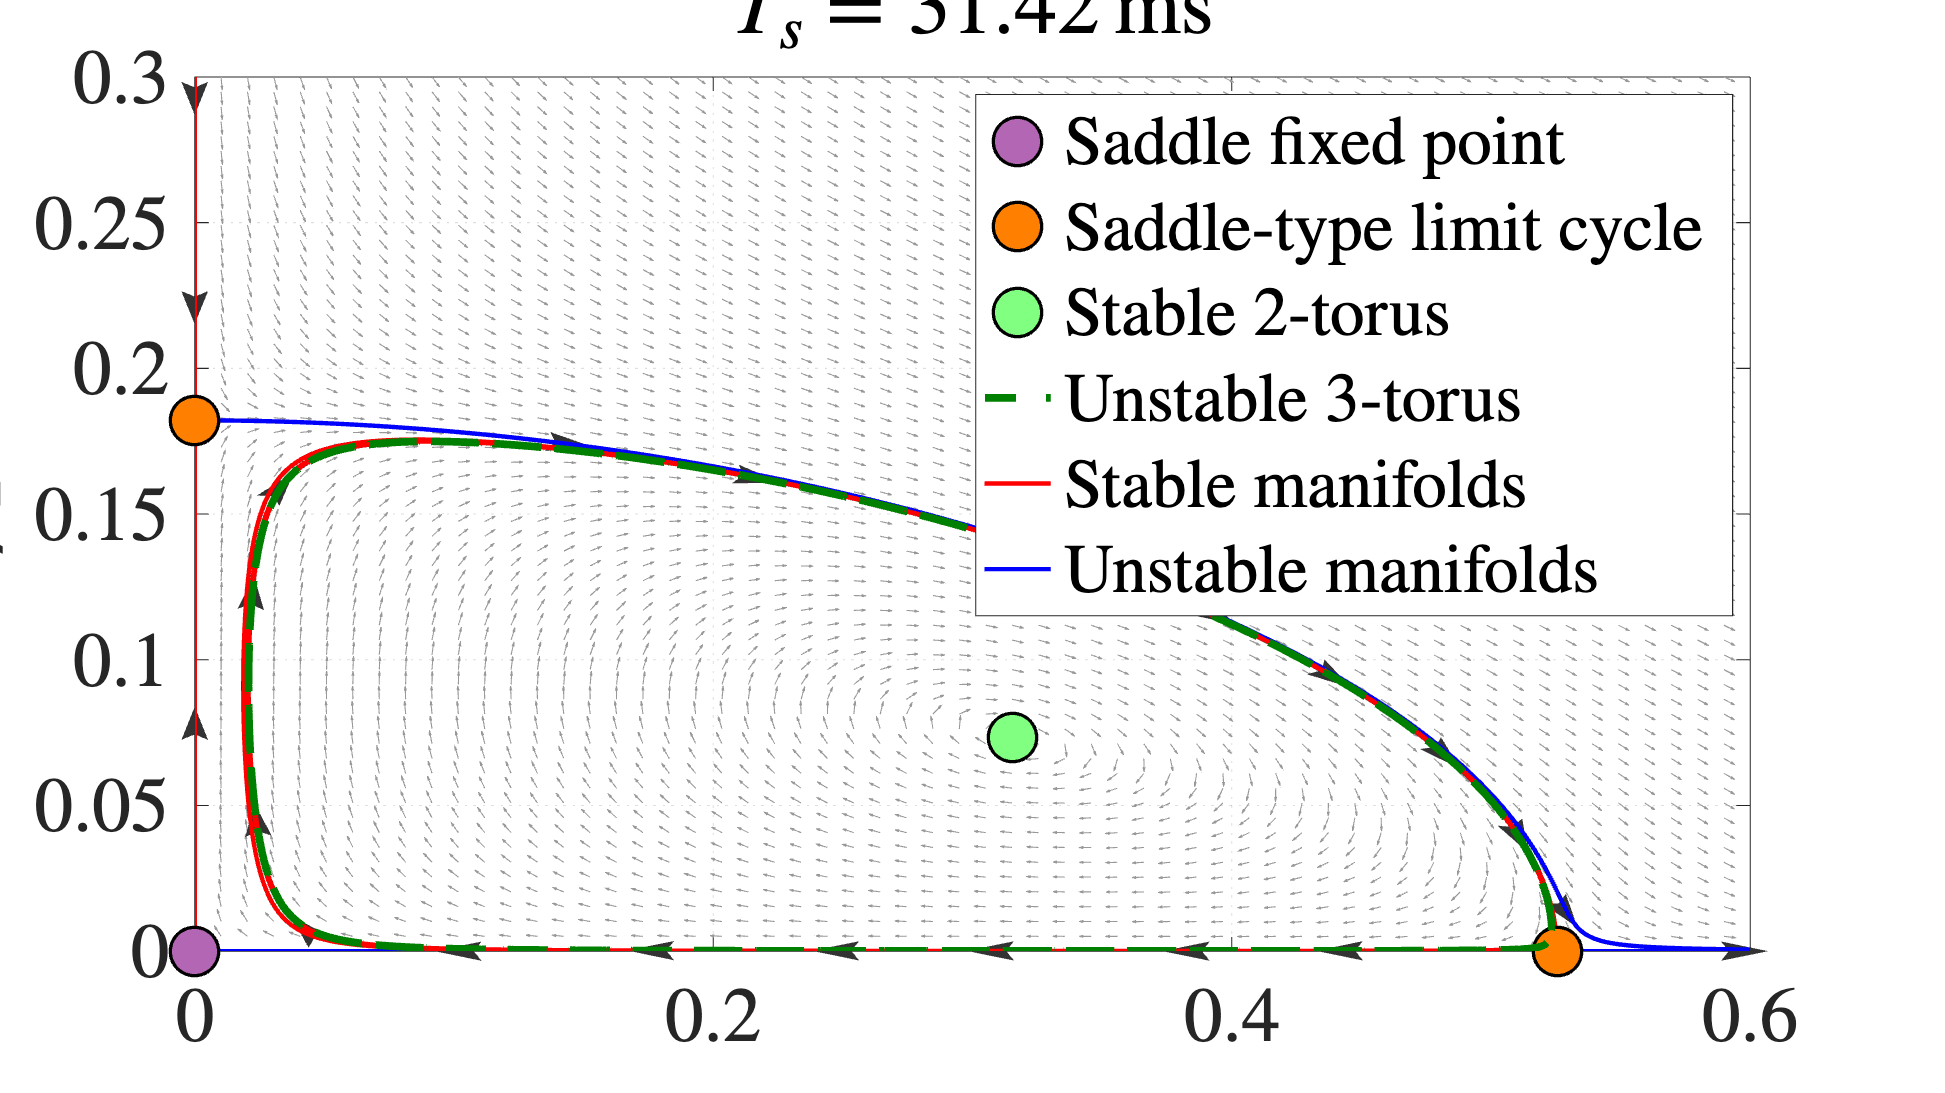

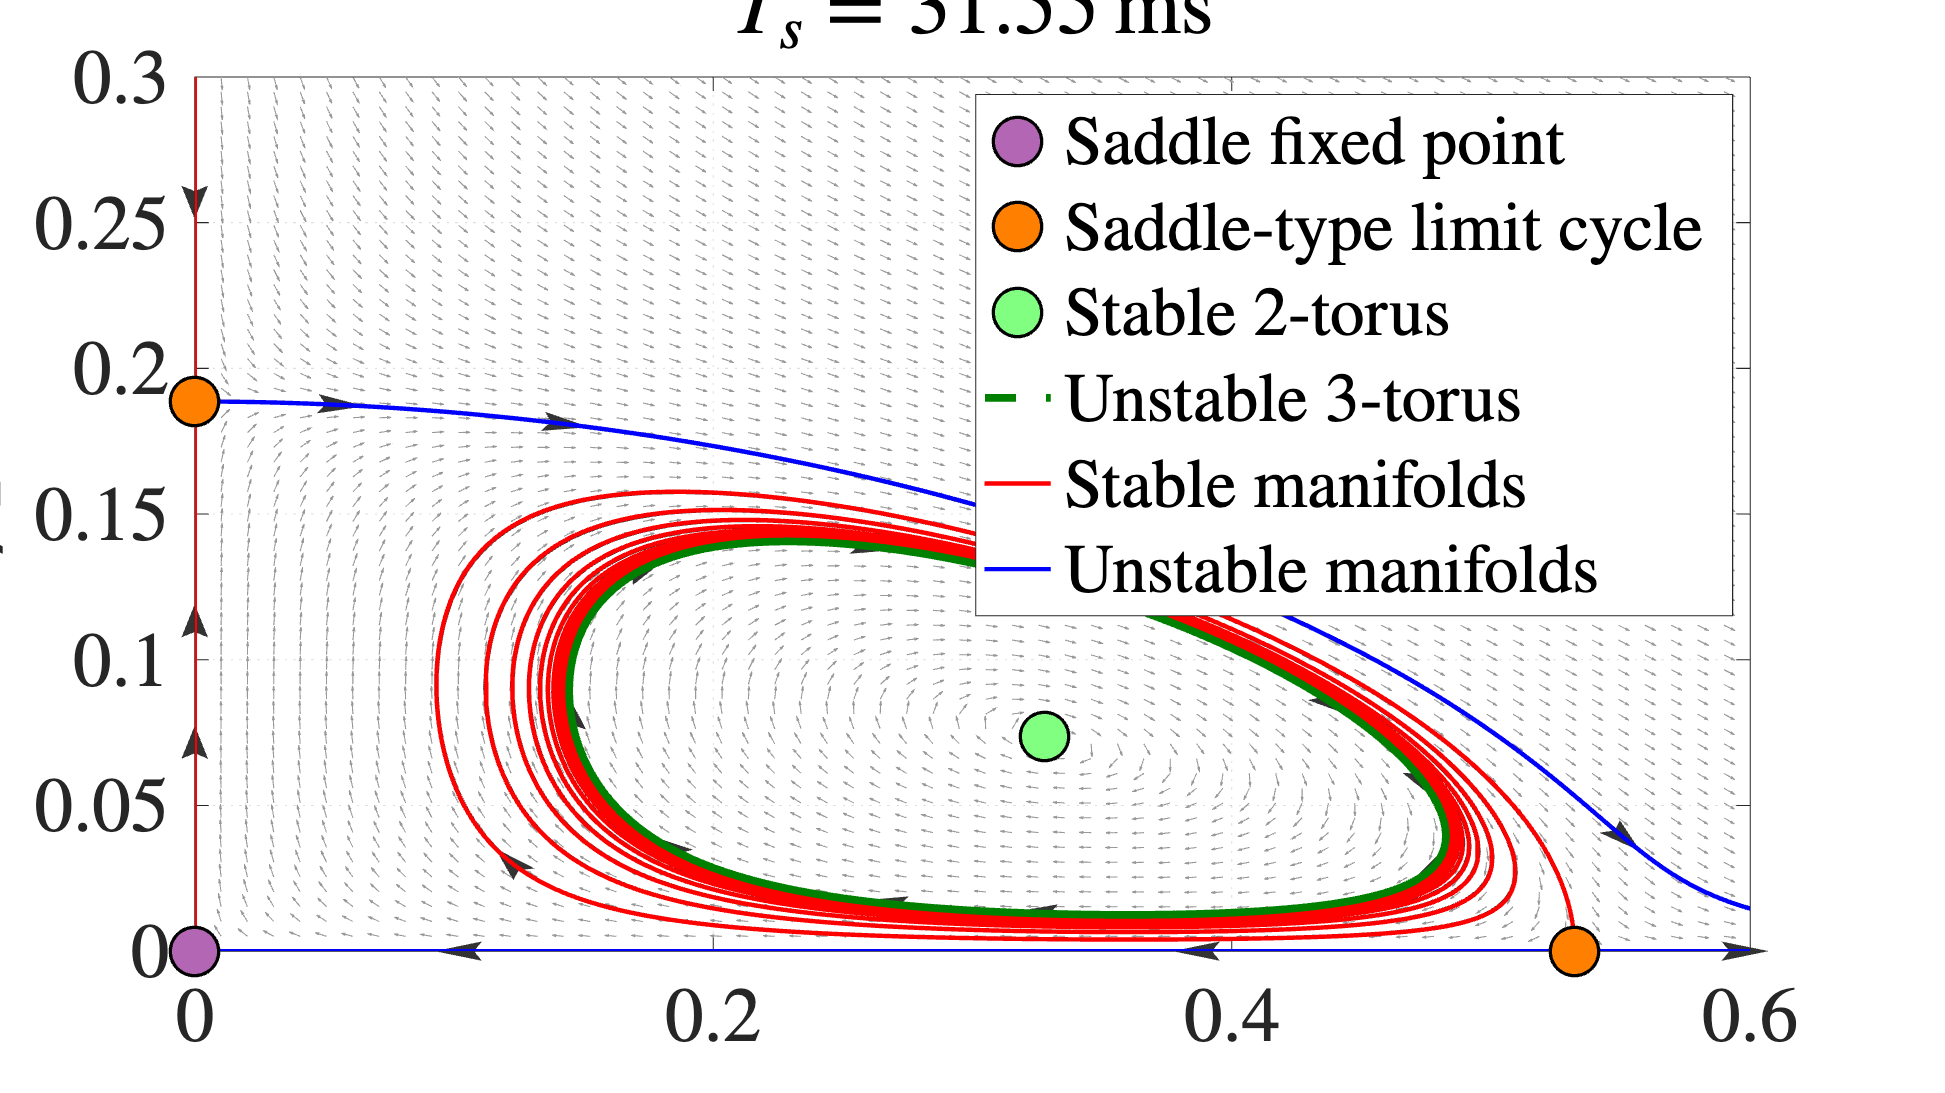

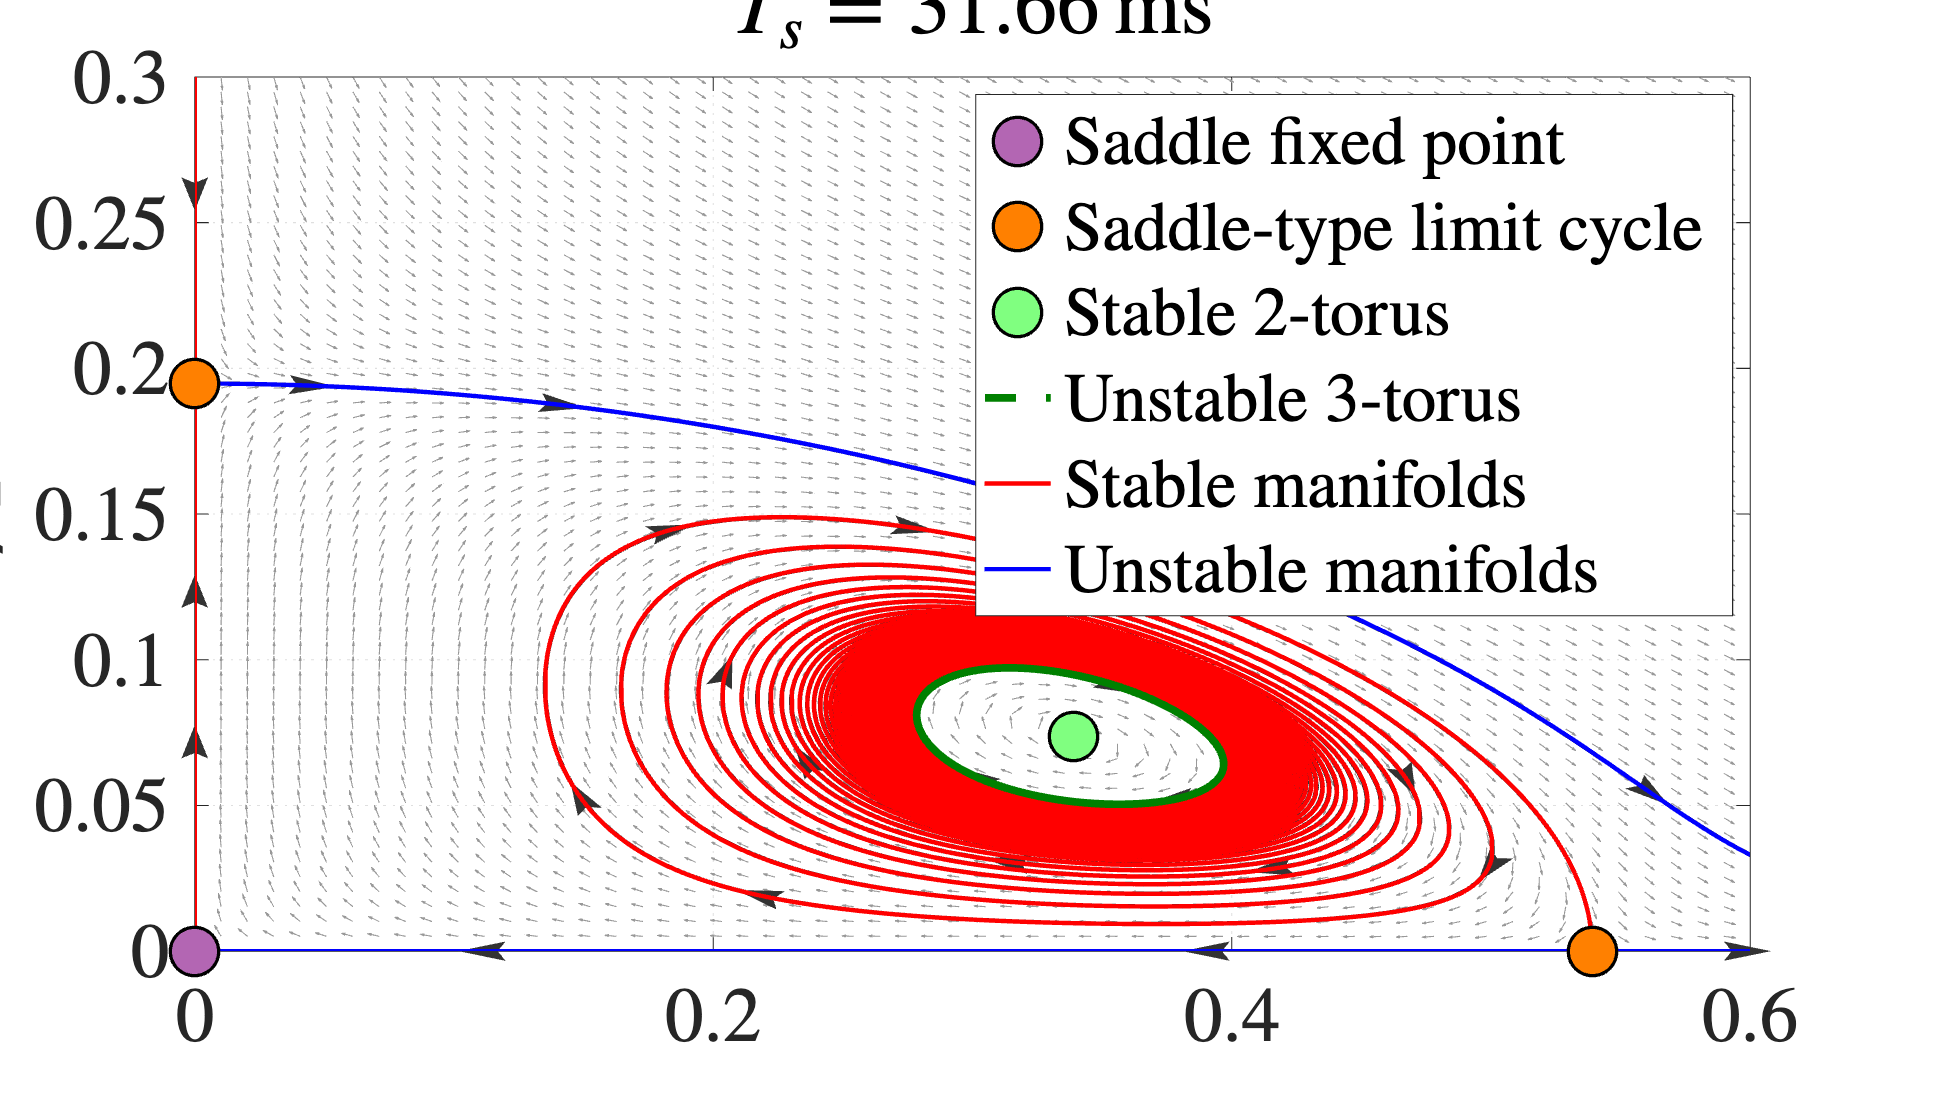

mu_queryPP     = [30.6, 31.2, 31.39:0.01:31.42, 31.55, 31.66:0.01:31.68, 31.8, 32.3]; % [ms]

oldStyle = get(groot,'DefaultFigureWindowStyle');
set(groot,'DefaultFigureWindowStyle','normal');
cleanupFig = onCleanup(@() set(groot,'DefaultFigureWindowStyle',oldStyle));

rho1rho2PP(interpStruct, mu_queryPP, config);

## Prediction Accuracy at Unseen Delay Values

The **Spectral Submanifold and its reduced dynamics are interpolated** at an **unseen feedback delay** value. Full-order trajectories of the delayed Furuta pendulum are generated, delay-embedded, and projected onto the interpolated SSM. The resulting trajectories are compared with those obtained by advecting the parametric reduced-order model from the initial conditions in reduced space and lifting them back to physical space. The **DTW error metric **is used to assess the accuracy of the parametric SSM-reduced model predictions.

mu_query   = 31.3;       % Ts sampling interval [ms]
T_final  = 70;         % [s]
intraTs  = 0.001;      % [s]
r        = deg2rad(6); % IC radius [rad]
lag       = 10;          
overEmbed = 125;  
sliceInt  = [0, T_final];  

generatexDataFullSystem(T_final, mu_query/1000, config, intraTs, config.Kp, config.Kd, r);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to parallel pool with 18 workers.



indTest   = [1,2];  
 InterpManifold(mu_query, config);

Manifold: 
 Interpolation method to be used to evaluate the model at mu_query = 31.30: linear
Employed training parameter values = [31.00 32.00]
 


 InterpDynamics(mu_query, config);

Dynamics:
 Interpolation method to be used to evaluate the model at mu_query = 31.30: linear
Employed training parameter values = [31.00 32.00]
 


Using interpolated IMInfo & RDInfo at k = 31.30 
The 134 embedding coordinates consist of the measured state and its 133 time-delayed measurements.
Test 1: DTW chosen (DTW error = 3.09%)
Test 2: DTW chosen (DTW error = 4.56%)
Error (DTW) average over test set = 3.82%


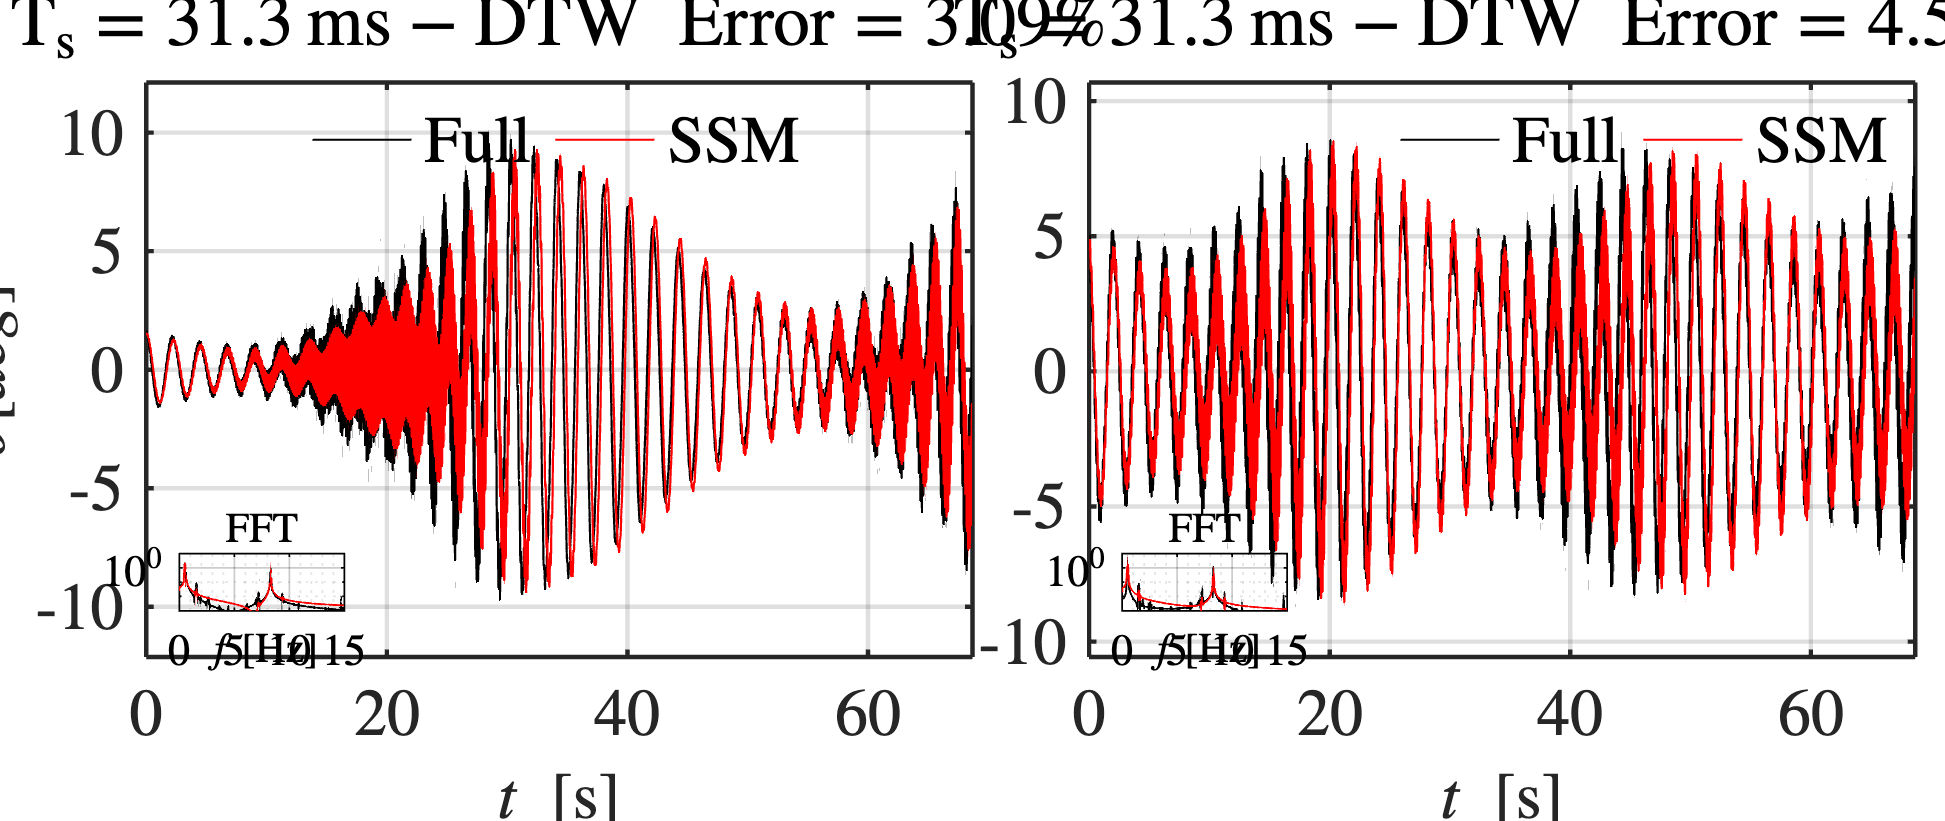


NMTEorDTW = 'DTW';         % 'DTW' | 'NMTE'
[yTrunc, yRec] = predict(mu_query, config, lag, overEmbed, indTest, sliceInt, NMTEorDTW, figOpts);

## **Basin of Attraction of the Stable 2-Torus**

Here, we evaluate whether the **SSM-reduced model** correctly reproduces the **basin of attraction (BoA)** of the stable invariant **2-torus** at a fixed delay value. **Three full-system trajectories, **two initialized inside and one outside the predicted BoA, are used to verify consistency between **full-system behavior** and **reduced-model BoA predictions.**

mu_BoA  = 31.6; 
baseDir = 'BasinOfAttraction31.6ms';

load(fullfile(baseDir, 'RDInfo31.6SSMLearn.mat'), 'RDInfo');  
load(fullfile(baseDir, 'IMInfo31.6SSMLearn.mat'), 'IMInfo'); 
load(fullfile(baseDir, 'xDataKp_15.5_Kd_5.45.mat'), 'xData');

invT = RDInfo.inverseTransformation.map; 
xDataIC = cell(3,2);
xDataDE = cell(3,2);
for ii = 1:3
    xDataIC{ii,1}(1,1:10000)   = xData{ii,1}(1:10000);
    xDataIC{ii,2}(1,1:10000)   = xData{ii,2}(1,1:10000);
    xDataDE{ii,1}(1,:)   = xData{ii,1}(1:end);
    xDataDE{ii,2}(1,:)   = xData{ii,2}(1,1:end);
end

[yIC, opts_embd] = coordinatesEmbedding( ...
    xDataIC, config.SSMDim, 'OverEmbedding', overEmbed, 'ShiftSteps', lag); 

The 134 embedding coordinates consist of the measured state and its 133 time-delayed measurements.


[yDataDE, opts_embd] = coordinatesEmbedding( ...
    xDataDE, config.SSMDim, 'OverEmbedding', overEmbed, 'ShiftSteps', lag); 

The 134 embedding coordinates consist of the measured state and its 133 time-delayed measurements.


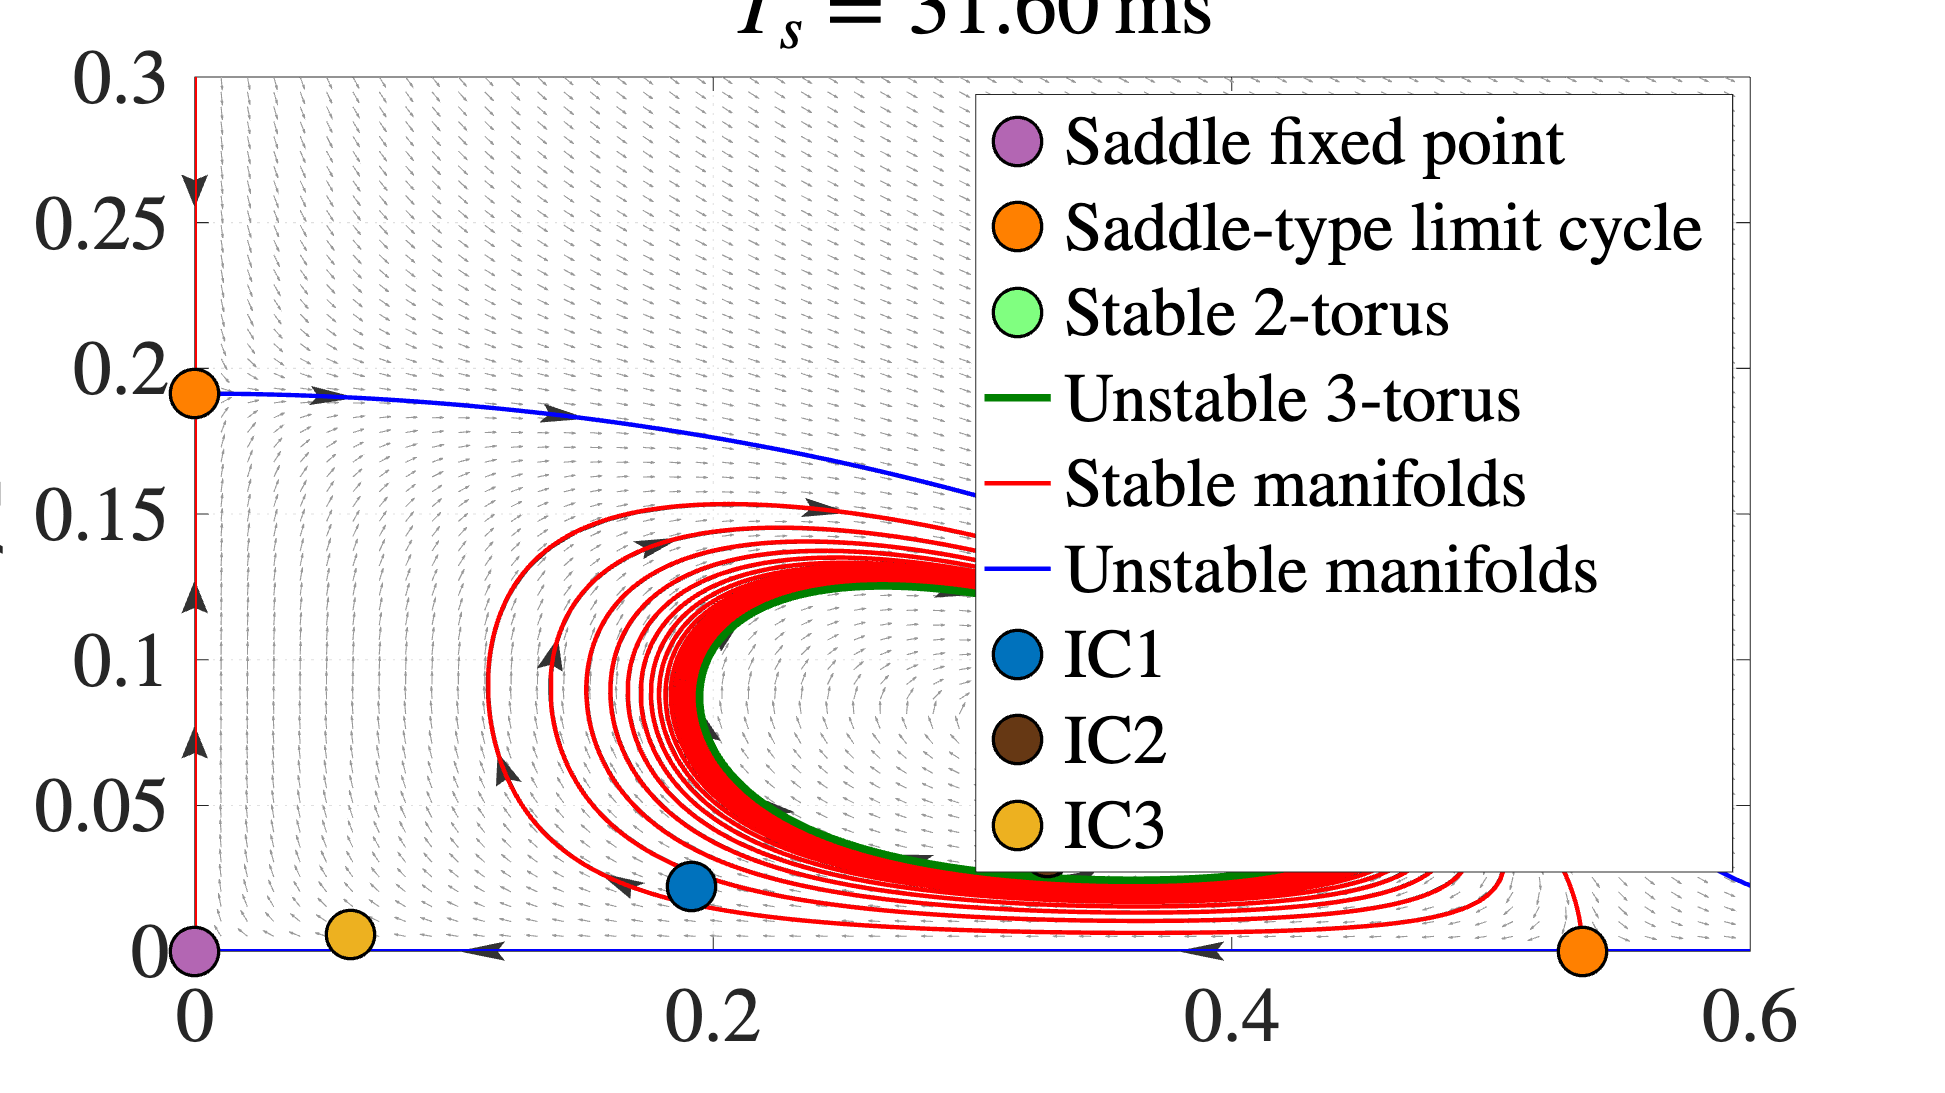


etaIC   = projectTrajectories(IMInfo, yIC);
zIC     = transformTrajectories(invT, etaIC);
polarIC = convertComplexToPolar(zIC);

ICrho1rho2 = [ ...
    polarIC{1,2}([1,3],1)'; ...
    polarIC{2,2}([1,3],1)'; ...
    polarIC{3,2}([1,3],1)'  ...
];

BoA(interpStruct, mu_BoA, config, ICrho1rho2);

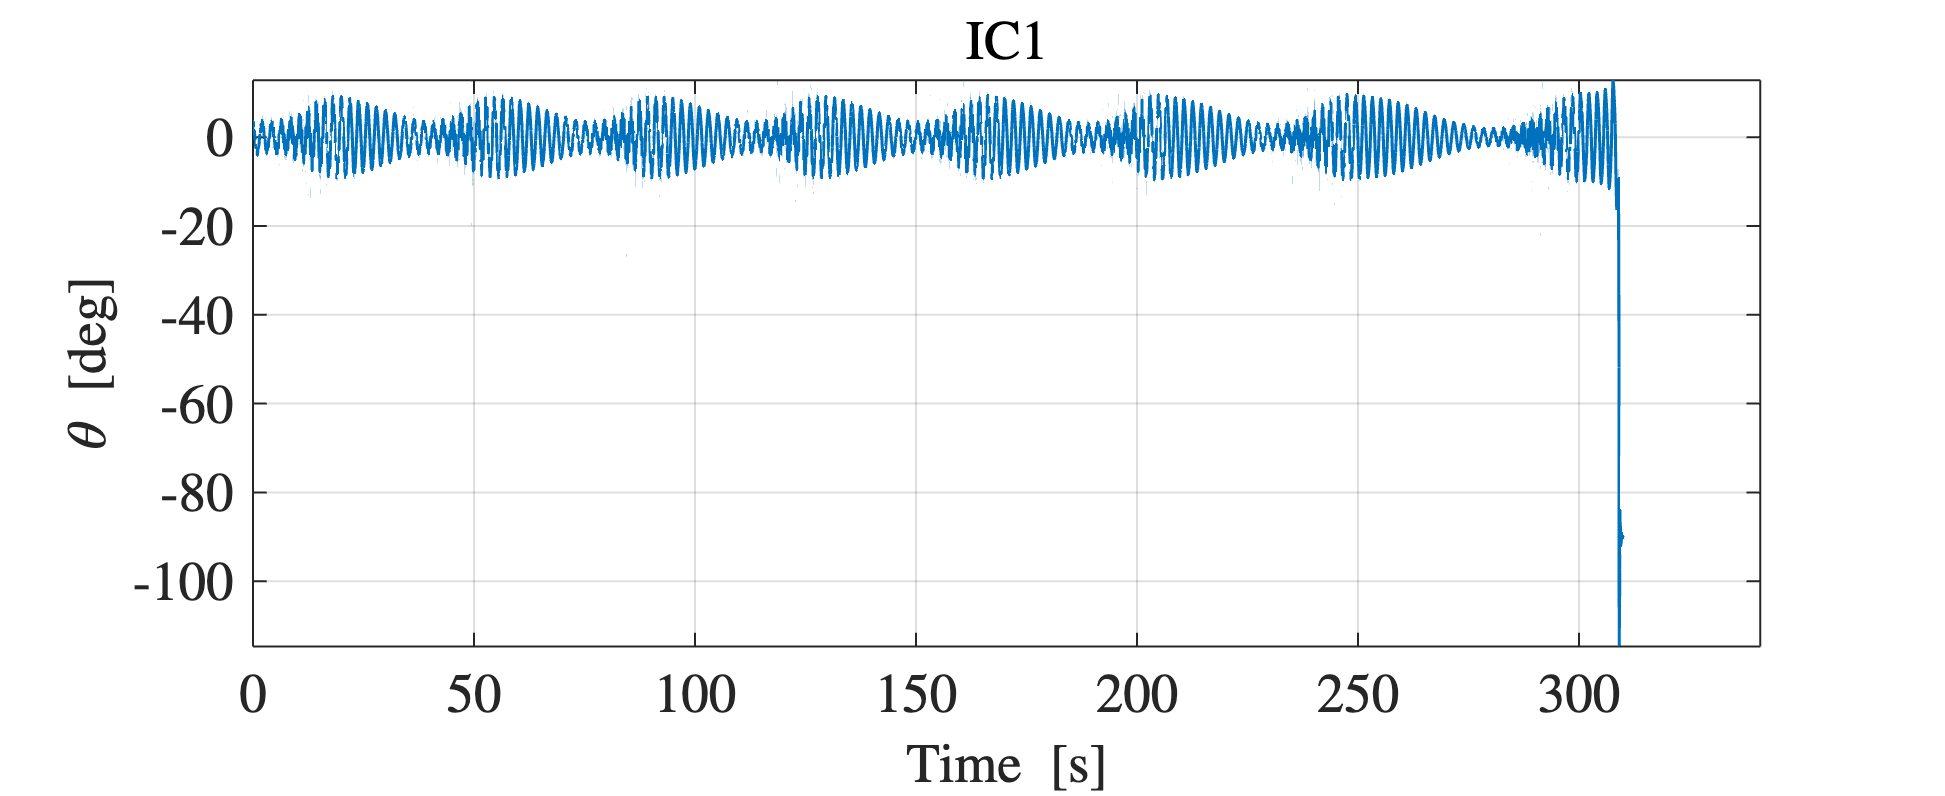

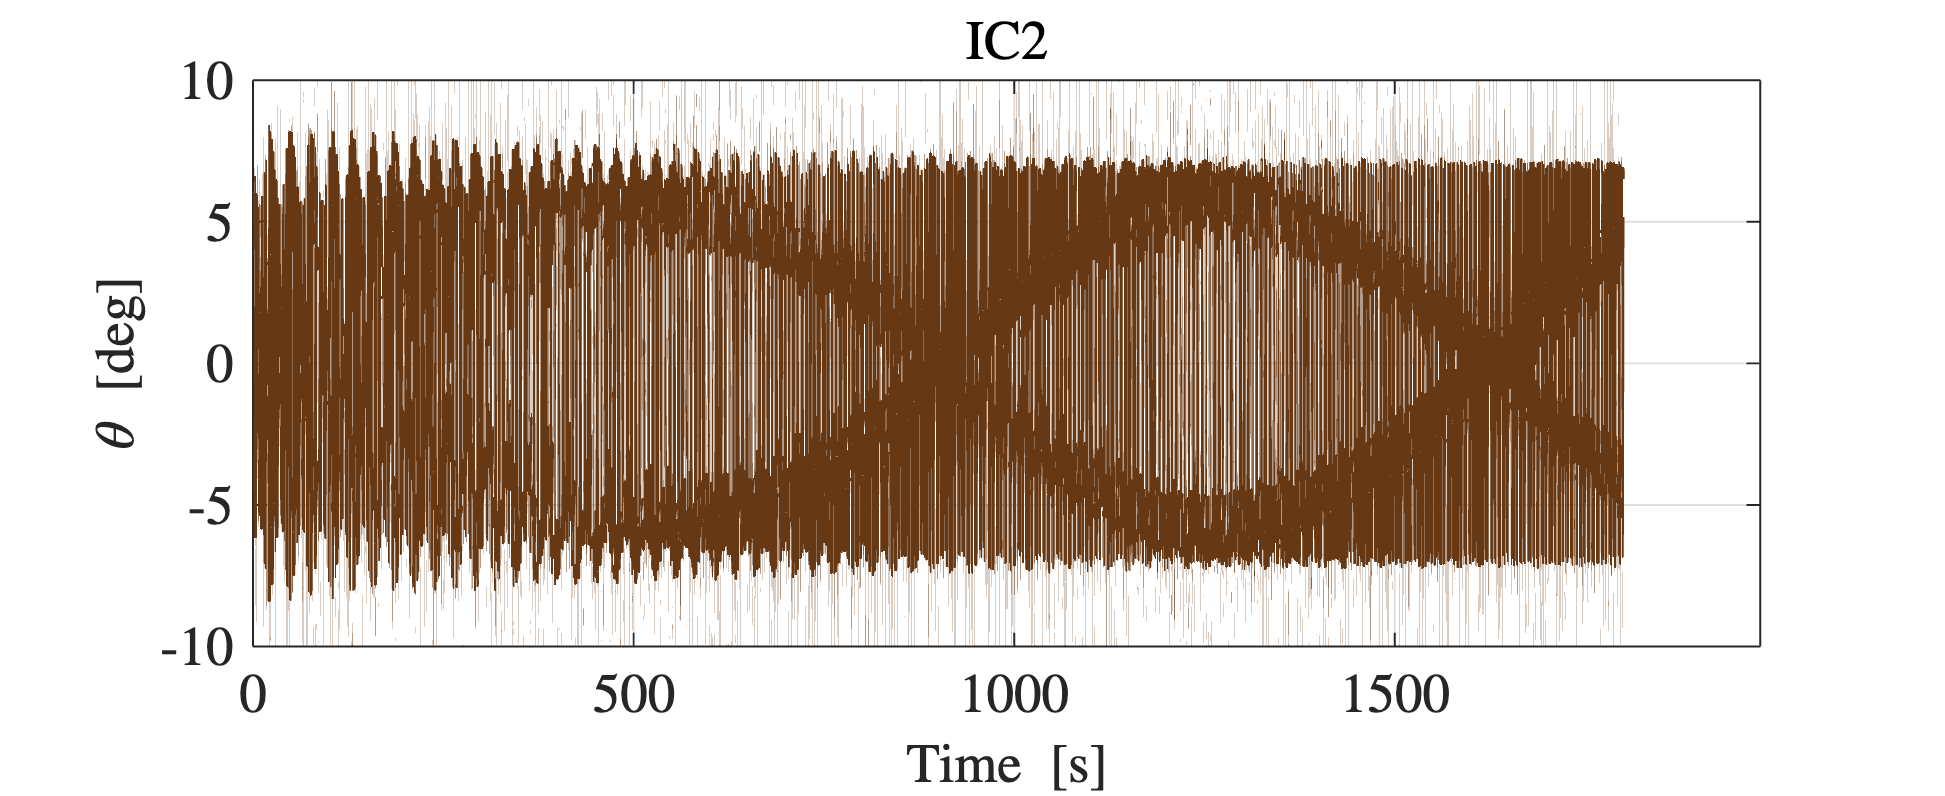

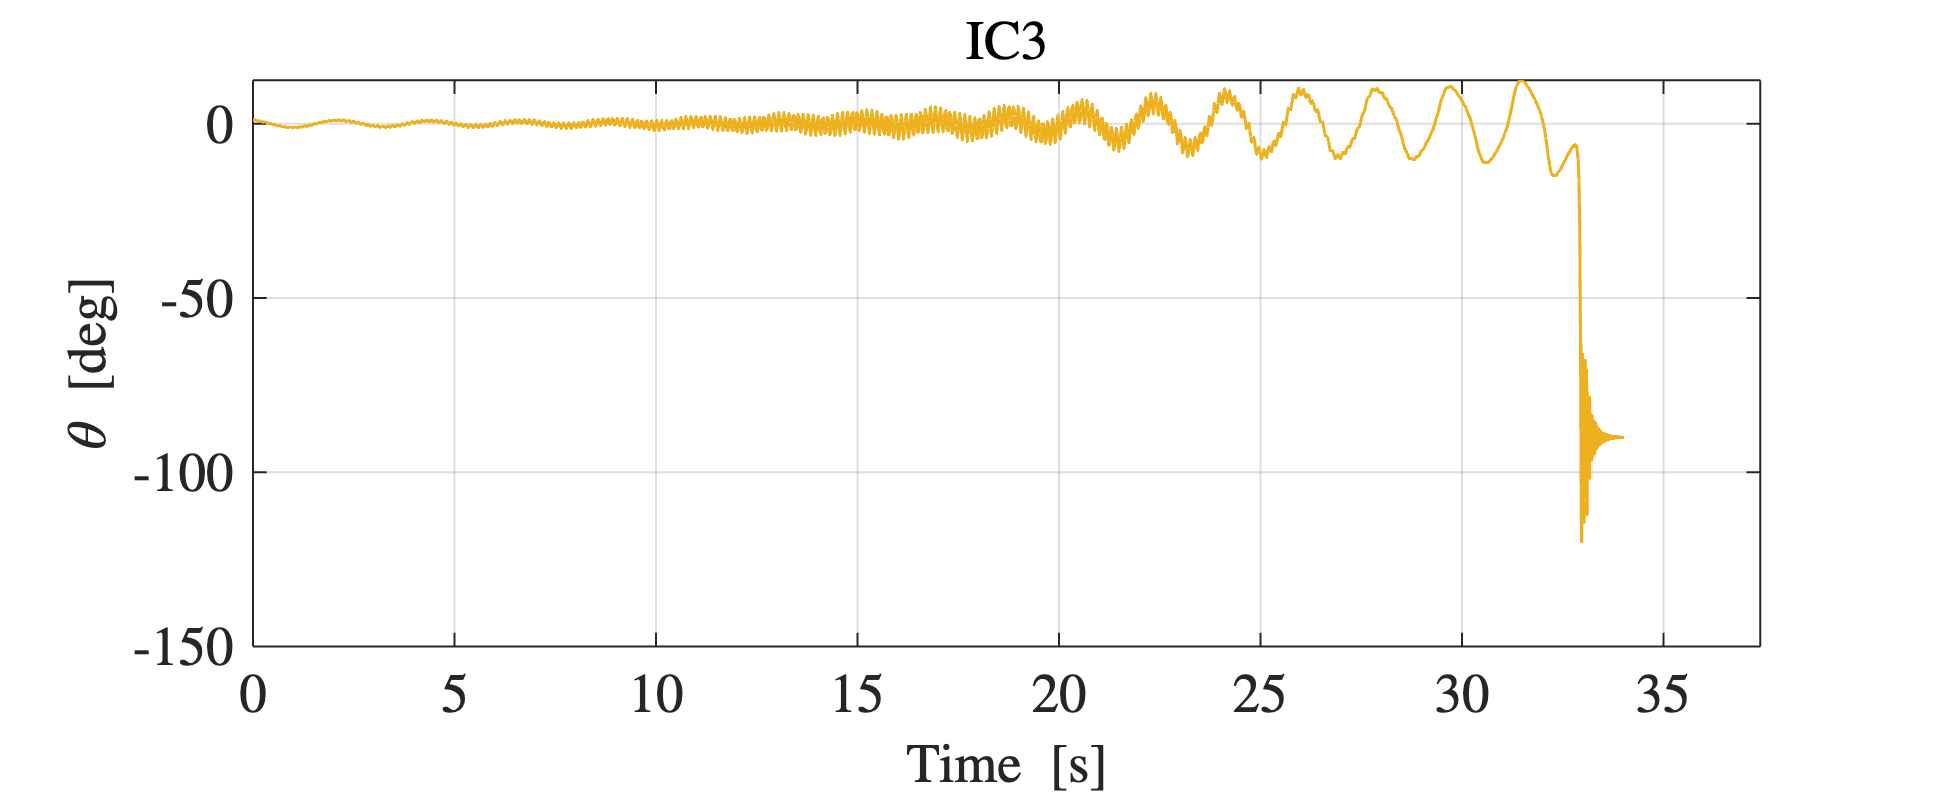

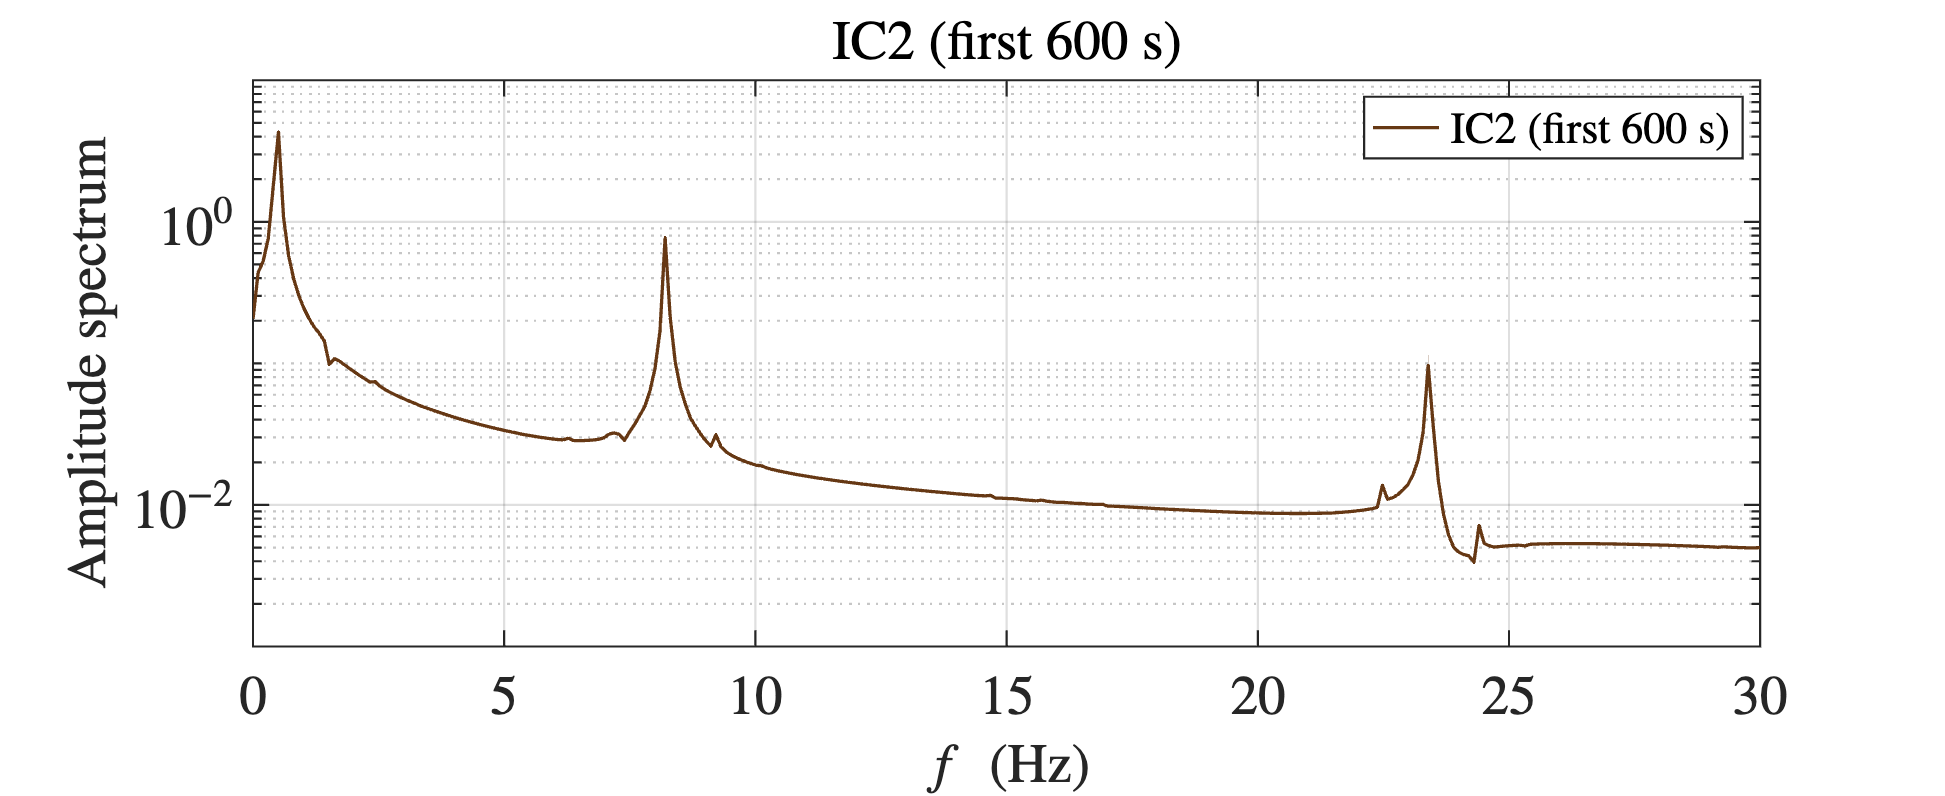

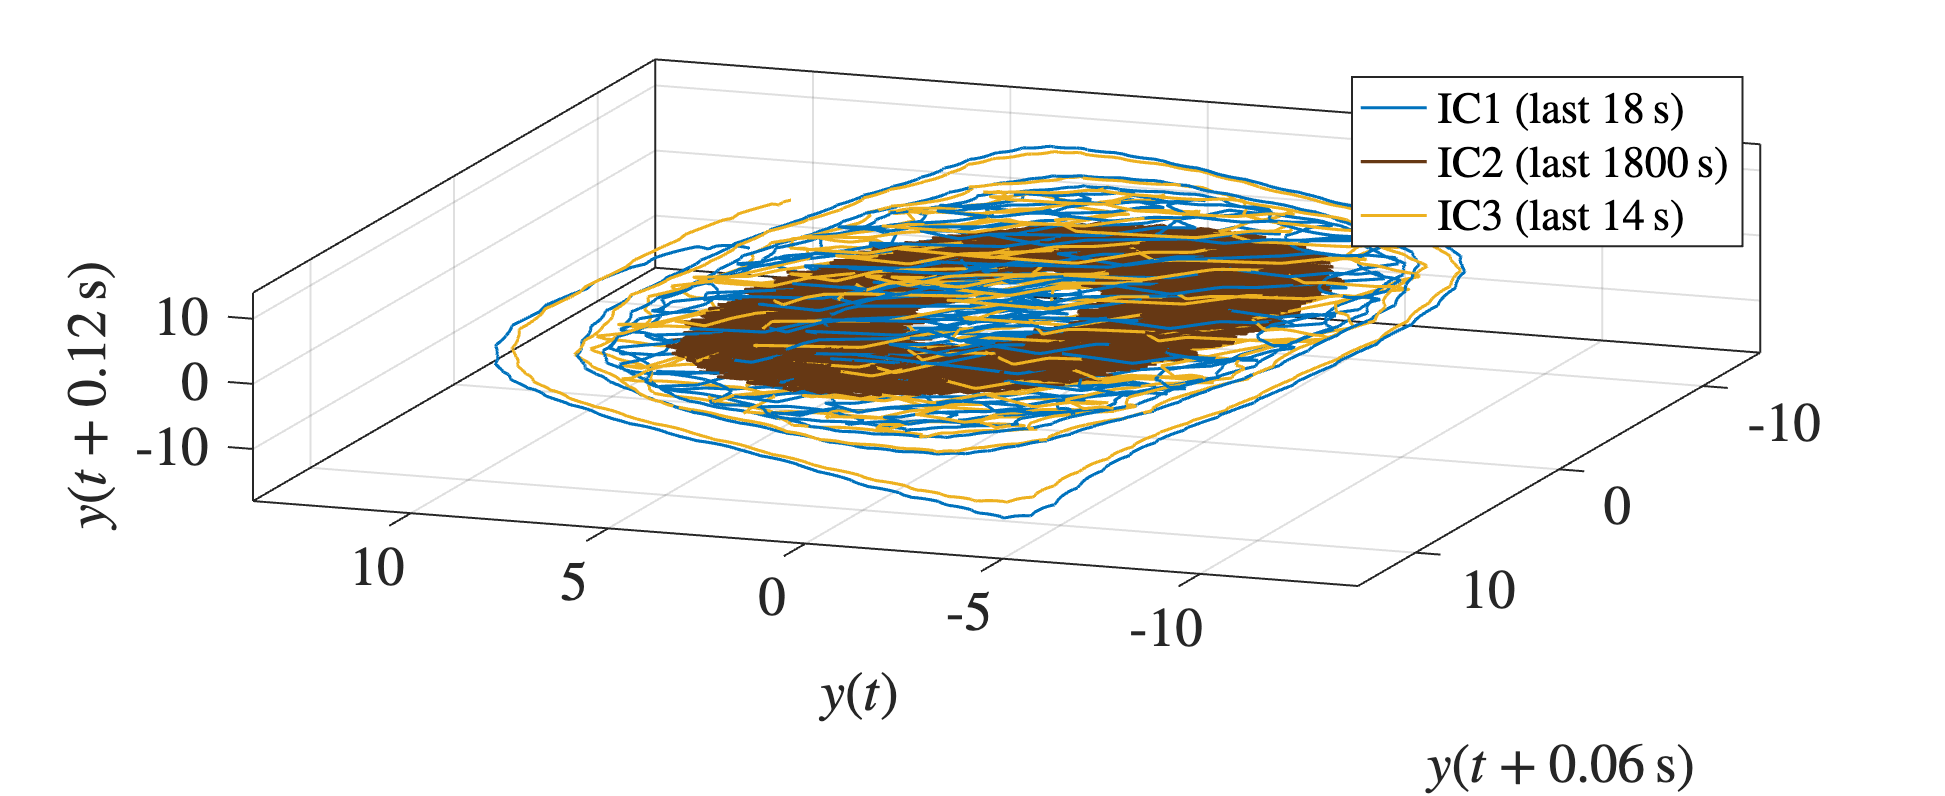

plotICandFFT(xData, xDataIC, yDataDE);